# Radio FM Stereo

Load signal

fs = 3.2e6;         % sampling frequency
N  = 32e6;         % number of samples (IQ)
fc = 0.40e6;        % central frequency of MF station

f = fopen('samples_100MHz_fs3200kHz.raw');
s = fread(f, 2*N, 'uint8');
fclose(f);

s = s-127;

%% IQ --> complex
wideband_signal = s(1:2:end) + sqrt(-1)*s(2:2:end); clear s;

%% Extract carrier of selected service, then shift in frequency the selected service to the baseband
wideband_signal_shifted = wideband_signal .* exp(-1i*2*pi*fc/fs*[0:N-1]');

%% Filter out the service from the wide-band signal

Astop = 40; % t�umienie w pa�mie zaporowym 
Fstop = 80e3 + 2000; % od tego moemntu t�umie
Fpass = 80e3; %przepuszaczna mx czestotliwo��
Apass = 3;

LowPassSpec = fdesign.lowpass(Fpass, Fstop, Apass, Astop,3.2e6);
LowPassFilter1 = design(LowPassSpec,'ellip');

[b, a] = tf(LowPassFilter1);
wideband_signal_filtered = filter( b, a, wideband_signal_shifted );

%% Down-sample to service bandwidth - bwSERV = new sampling rate
bwSERV = 80e3; bwAUDIO = 16e3;   
x = decimate(wideband_signal_filtered,20);
fs = fs/20;
%% FM demodulation
dx = x(2:end).*conj(x(1:end-1));
y = atan2( imag(dx), real(dx) );

Sygnal mono

N=128;
mono.b = fir1(N,[30/80e3 15e3/80e3],blackmanharris(N+1));

y_audio =  filter(mono.b,1,y);
ym = decimate(y_audio,5); 

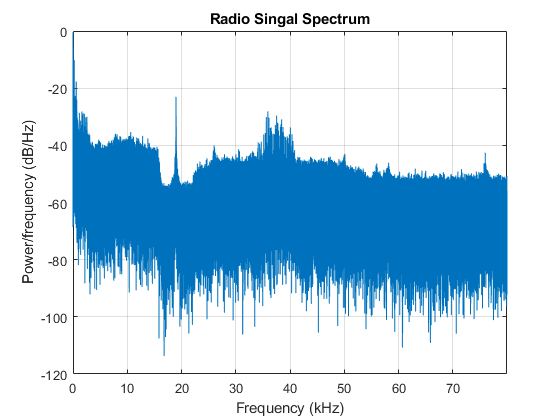

% plot input power spectral density 
figure
periodogram(y,rectwin(length(y)),length(y),fs)
title('Radio Singal Spectrum');

#### Pilot

% filtr pilota
N=128; 
pilot.b = fir1(N*4,[(19e3-10)/bwSERV (19e3+10)/bwSERV],blackmanharris(N*4+1));
[pilot.h,pilot.f] = freqz(pilot.b,1,0.1:0.05:bwSERV,bwSERV);
pilot.y =  filter(pilot.b,1,y);


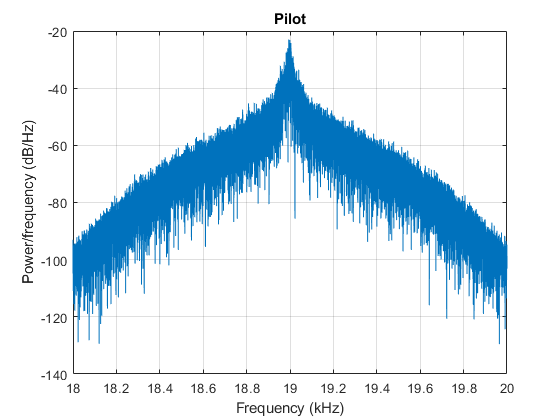

figure(3);
periodogram(pilot.y,rectwin(length(pilot.y)),length(pilot.y),fs)
xlim([18 20])
title('Pilot');

#### L-R

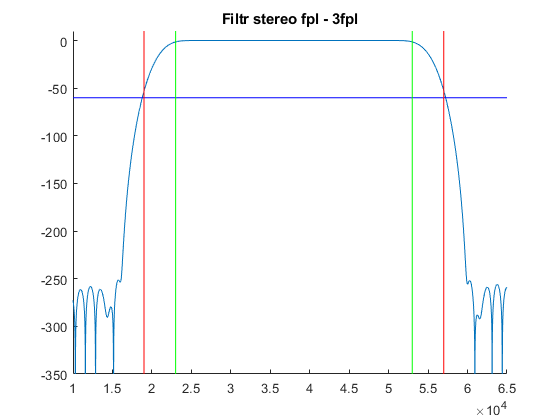

%[fpr,~] = max(periodogram(pilot.y,rectwin(length(pilot.y)),length(pilot.y),fs));
fpr = 18994;

% czemu tak?
%stereo.b = fir1(N,[(fpr)/bwSERV (3*fpr)/bwSERV],blackmanharris(N+1));
stereo.b = fir1(N,[(21e3)/bwSERV (55e3)/bwSERV],blackmanharris(N+1));

[stereo.h,stereo.f] = freqz(stereo.b,1,0.1:0.5:80e3,80e3);
figure
hold on
plot(2*stereo.f,20*log(abs(stereo.h)),[0 80e3],[-60 -60],'b-')
plot([23e3 23e3],[-350 10],'g-');
plot([53e3 53e3],[-350 10],'g-');
plot([fpr fpr],[-350 10],'r-');
plot([fpr*3 fpr*3],[-350 10],'r-');
xlim([10e3 65e3]);
ylim([-350 10])
title('Filtr stereo fpl - 3fpl');

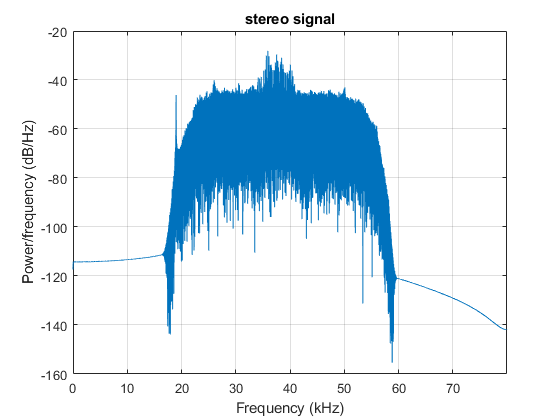



y_stereo = filter(stereo.b,1,y);
figure
periodogram(y_stereo,rectwin(length(y_stereo)),length(y_stereo),fs)
title('stereo signal');

signal translation 

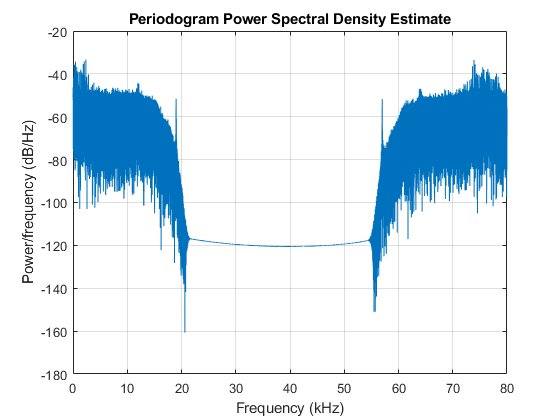

c = cos(2*pi*(19e3/bwSERV)*[0:length(y_stereo)-1]);
y_stereo_trans = y_stereo.*c';
figure
periodogram(y_stereo_trans,rectwin(length(y_stereo)),length(y_stereo),fs)
xlim([0 80])

4)

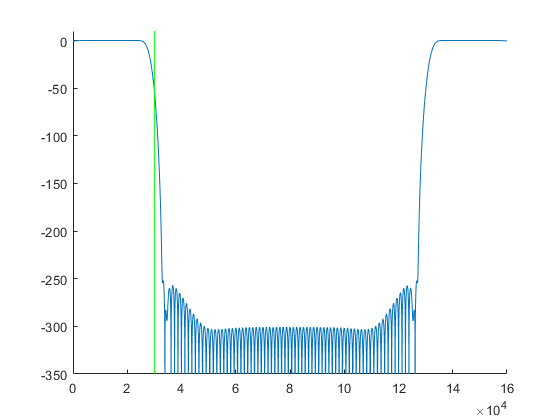

N = 128;
filtered.b = fir1(N,[30/80e3 28e3/80e3],blackmanharris(N+1));
[filtered.h,filtered.f] = freqz(filtered.b,1,0.1:0.5:80e3,80e3);

figure
hold on
plot(2*filtered.f,20*log(abs(filtered.h)))
ylim([-350 10])
plot([30e3 30e3],[-350 10],'g-');

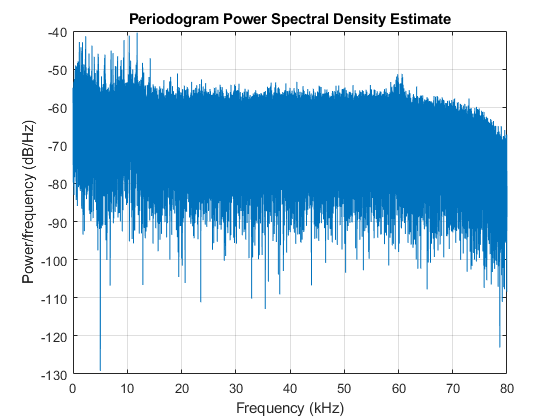



y_stereo_filtered  = filter(filtered.b,1,y_stereo_trans);
y_stereo_filtered = resample(y_stereo_filtered,16,80);

figure
periodogram(y_stereo_filtered,rectwin(length(y_stereo_filtered)),length(y_stereo_filtered),fs)

Rekonstrukcja

%% yl and yr
ym = ym-mean(ym);
ym = ym/(1.001*max(abs(ym)));


y_stereo_filtered = y_stereo_filtered-mean(y_stereo_filtered);
y_stereo_filtered = y_stereo_filtered./(1.001*max(abs(y_stereo_filtered)));
yl = 0.5*(ym+y_stereo_filtered);
yr = 0.5*(ym-y_stereo_filtered);


y_kek = [yl yr];
%% Listen stereo to the final result 
%soundsc( y_kek, bwAUDIO*2);
%% Listen mono to the final result 
%soundsc(ym,bwAUDIO*2)